clc

## Problem 1: SIR Model

## Constant inputs

Population N = 350 million

N = 350000000;

Recovery time Tr = 15 days

Tr = 15;

Contacts time Tc = 7.5 days

Tc = 7.5;

Initial infected population

I0 = 5000;

## a.Calculate R0 and N/S(0), where N/S(0)=R0

R0 = Tr/Tc

R0 = 2

## b.Plot I-t

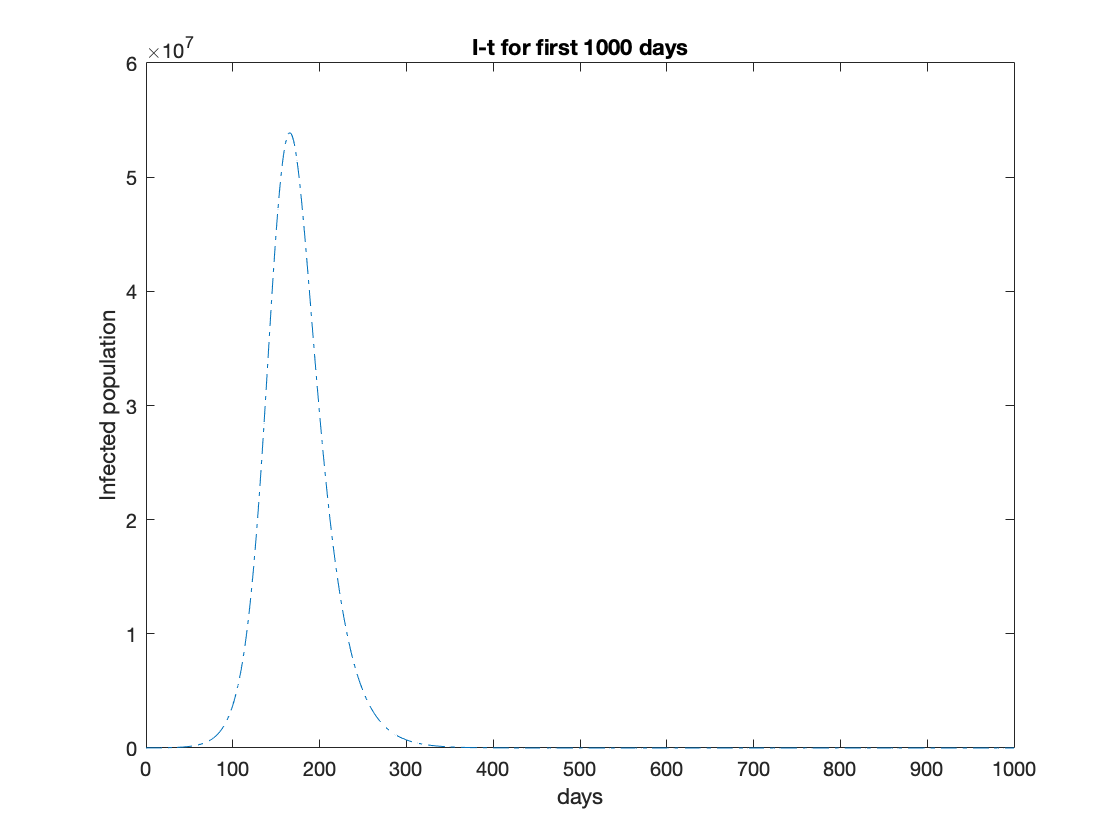

tspan = (0:1000);
y0 = [N-I0,I0];
[t,y] = ode45(@(t,y) odefun(t,y,N,Tr,Tc),tspan,y0);
plot(t,y(:,2),'-.')
fraction1 = max(y(:,2))/N;
title('I-t for first 1000 days')
xlabel('days')
ylabel('Infected population')
hold on

## c.Tc = 1.4*Tc

Tc = 1.4*Tc;
[t,y] = ode45(@(t,y) odefun(t,y,N,Tr,Tc),tspan,y0);
plot(t,y(:,2),'-')
fraction2 = max(y(:,2))/N;

## d.Tc = 1.4*Tc(for t > 150)

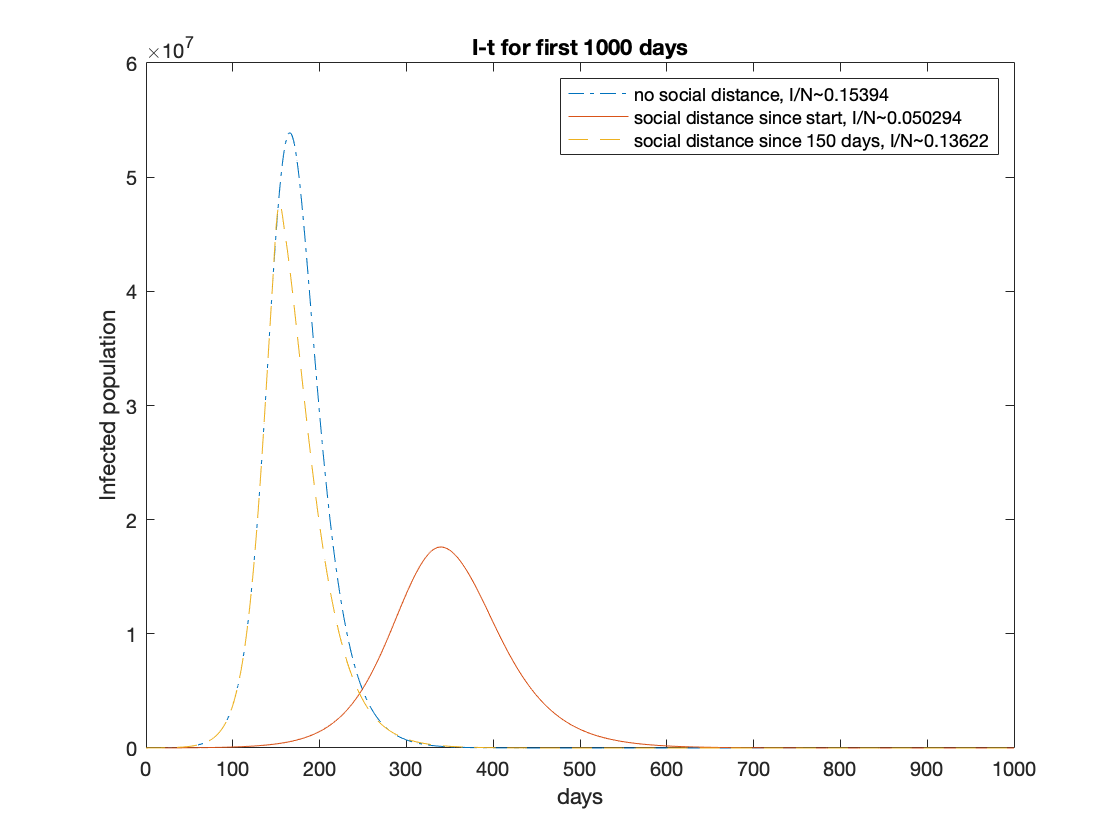

Tc = 7.5;
[t,y] = ode45(@(t,y) odefun(t,y,N,Tr,Tc+Tc*0.4*(t>150)),tspan,y0);
plot(t,y(:,2),'--')
hold off
fraction3 = max(y(:,2))/N;
legend(['no social distance, I/N~' num2str(fraction1)],['social distance since start, I/N~' num2str(fraction2)],['social distance since 150 days, I/N~' num2str(fraction3)])

## Function definition [S=y(1),I=y(2)]

function dydt = odefun(t,y,N,Tr,Tc)
dydt = zeros(2,1);
dydt(1) = - y(2)*y(1)/(N*Tc);
dydt(2) = y(2)*y(1)/(N*Tc)-y(2)/Tr;
end